% ========================================================
% === SCRIPT COMPLETO: PIPELINE SVD_BC + GCN SU YALE    ===
% ========================================================
clear; clc; close all;
rng(0);
tic;

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot  = '/Users/giuseppebonomo/.../ProgettoMetodi';
addpath(genpath(projectRoot));

results_path = fullfile(pwd,'results_yale_svd_fulltrain');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella %s\n', results_path);
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI GLOBALI
%% ----------------------------------------------------------------
tol              = 1e-4;
maxit            = 1000;
energy_threshold = 0.95;   % soglia energia PCA
K_neighbors      = 10;     % vicini per grafo
epochs           = 500;    % come hai sperimentato
learning_rate    = 0.5;    % come hai sperimentato

%% ----------------------------------------------------------------
%% 2) CARICAMENTO YALE & NORMALIZZAZIONE
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset Yale...\n');

>>> Caricamento dataset Yale...


load('dataset/volti_dataset_Yale.mat');    % A (m×n), labels
A      = double(A) / 255;                  % porta in [0,1]
labels = labels(:);
[n_pixels, n] = size(A);
num_classes   = max(labels);

%% ----------------------------------------------------------------
%% 3) CALCOLO VOLTO MEDIO & CENTRATURA
%% ----------------------------------------------------------------
mean_face  = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
A_centered = A - mean_face;

%% ----------------------------------------------------------------
%% 4) SVD_BC su dati centrati
%% ----------------------------------------------------------------
fprintf('>>> Lancio svd_BC...\n');

>>> Lancio svd_BC...


[U, S, ~] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 165x165 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=165 ... 

iter=1001 time=3.02 s
         [qr_eig] deflazione k=164 ... 

iter=1001 time=2.53 s
         [qr_eig] deflazione k=163 ... 

iter=1001 time=3.03 s
         [qr_eig] deflazione k=162 ... iter=338 time=0.76 s
         [qr_eig] deflazione k=161 ... 

iter=1001 time=2.61 s
         [qr_eig] deflazione k=160 ... iter=309 time=1.28 s
         [qr_eig] deflazione k=159 ... 

iter=1001 time=2.19 s
         [qr_eig] deflazione k=158 ... 

iter=1001 time=2.20 s
         [qr_eig] deflazione k=157 ... 

iter=1001 time=1.99 s
         [qr_eig] deflazione k=156 ... iter=765 time=1.47 s
         [qr_eig] deflazione k=155 ... 

iter=1001 time=2.00 s
         [qr_eig] deflazione k=154 ... 

iter=1001 time=1.84 s
         [qr_eig] deflazione k=153 ... 

iter=1001 time=1.93 s
         [qr_eig] deflazione k=152 ... 

iter=1001 time=1.85 s
         [qr_eig] deflazione k=151 ... 

iter=1001 time=1.92 s
         [qr_eig] deflazione k=150 ... 

iter=1001 time=1.87 s
         [qr_eig] deflazione k=149 ... 

iter=1001 time=2.33 s
         [qr_eig] deflazione k=148 ... 

iter=1001 time=1.66 s
         [qr_eig] deflazione k=147 ... 

iter=1001 time=2.29 s
         [qr_eig] deflazione k=146 ... 

iter=1001 time=1.81 s
         [qr_eig] deflazione k=145 ... 

iter=1001 time=2.39 s
         [qr_eig] deflazione k=144 ... 

iter=1001 time=1.94 s
         [qr_eig] deflazione k=143 ... 

iter=1001 time=1.88 s
         [qr_eig] deflazione k=142 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=141 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=140 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=139 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=138 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=137 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=136 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=135 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=134 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=133 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=132 ... 

iter=1001 time=0.86 s
         [qr_eig] deflazione k=131 ... 

iter=1001 time=0.89 s
         [qr_eig] deflazione k=130 ... 

iter=1001 time=0.82 s
         [qr_eig] deflazione k=129 ... 

iter=1001 time=0.81 s
         [qr_eig] deflazione k=128 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=127 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=126 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=125 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=124 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=123 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=122 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=121 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=120 ... iter=90 time=0.06 s
         [qr_eig] deflazione k=119 ... 

iter=1001 time=0.70 s
         [qr_eig] deflazione k=118 ... 

iter=1001 time=0.68 s
         [qr_eig] deflazione k=117 ... 

iter=1001 time=0.68 s
         [qr_eig] deflazione k=116 ... 

iter=1001 time=0.66 s
         [qr_eig] deflazione k=115 ... 

iter=1001 time=0.66 s
         [qr_eig] deflazione k=114 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=113 ... iter=514 time=0.33 s
         [qr_eig] deflazione k=112 ... 

iter=1001 time=0.61 s
         [qr_eig] deflazione k=111 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=110 ... 

iter=1001 time=0.60 s
         [qr_eig] deflazione k=109 ... 

iter=1001 time=0.60 s
         [qr_eig] deflazione k=108 ... 

iter=1001 time=0.57 s
         [qr_eig] deflazione k=107 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=106 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=105 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=104 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=103 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=102 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=101 ... iter=989 time=0.51 s
         [qr_eig] deflazione k=100 ... 

iter=1001 time=0.51 s
         [qr_eig] deflazione k=99 ... 

iter=1001 time=0.50 s
         [qr_eig] deflazione k=98 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=97 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=96 ... 

iter=1001 time=0.47 s
         [qr_eig] deflazione k=95 ... 

iter=1001 time=0.47 s
         [qr_eig] deflazione k=94 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=93 ... 

iter=1001 time=0.45 s
         [qr_eig] deflazione k=92 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=91 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=90 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=89 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=88 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=87 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=86 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=85 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=84 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=83 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=82 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=81 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=80 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=79 ... 

iter=1001 time=0.34 s
         [qr_eig] deflazione k=78 ... 

iter=1001 time=0.33 s
         [qr_eig] deflazione k=77 ... iter=344 time=0.11 s
         [qr_eig] deflazione k=76 ... 

iter=1001 time=0.31 s
         [qr_eig] deflazione k=75 ... 

iter=1001 time=0.31 s
         [qr_eig] deflazione k=74 ... 

iter=1001 time=0.38 s
         [qr_eig] deflazione k=73 ... 

iter=1001 time=0.30 s
         [qr_eig] deflazione k=72 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=71 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=70 ... iter=906 time=0.25 s
         [qr_eig] deflazione k=69 ... 

iter=1001 time=0.29 s
         [qr_eig] deflazione k=68 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=67 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=66 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=65 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=64 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=63 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=62 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=61 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=60 ... 

iter=1001 time=0.24 s
         [qr_eig] deflazione k=59 ... 

iter=1001 time=0.24 s
         [qr_eig] deflazione k=58 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=57 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=56 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=55 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=54 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=53 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=52 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=51 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... iter=2 time=0.00 s
         [qr_eig] deflazione k=48 ... 

iter=1001 time=0.22 s
         [qr_eig] deflazione k=47 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=46 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=45 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=41 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=40 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         

save(fullfile(results_path,'svd_data.mat'),'U','S');

%% ----------------------------------------------------------------
%% 5) Selezione di k da energia (σ²)
%% ----------------------------------------------------------------
sig2   = diag(S).^2;                  
energy = cumsum(sig2)/sum(sig2);
k      = find(energy >= energy_threshold, 1);
fprintf('>>> Seleziono k = %d (%.1f%% energia)\n', k, 100*energy(k));

>>> Seleziono k = 163 (96.4% energia)



%% ----------------------------------------------------------------
%% 6) Proiezioni PCA → X [n×k]
%% ----------------------------------------------------------------
U_k = U(:,1:k);
X   = (U_k' * A_centered)';   % [n_samples×k]

%% ----------------------------------------------------------------
%% 7) One-hot encoding
%% ----------------------------------------------------------------
Y = zeros(num_classes, n);
for i = 1:n
    Y(labels(i),i) = 1;
end

%% ----------------------------------------------------------------
%% 8) Costruzione grafo & normalizzazione
%% ----------------------------------------------------------------
A_graph = zeros(n);
for i = 1:n
    d    = sum((X - X(i,:)).^2,2);
    [~,ix] = sort(d);
    A_graph(i, ix(2:K_neighbors+1)) = 1;
end
A_graph = max(A_graph, A_graph');   % simmetrico
A_hat   = A_graph + eye(n);         % self-loops
D       = diag(sum(A_hat,2));
A_norm  = D^(-0.5) * A_hat * D^(-0.5);

%% ----------------------------------------------------------------
%% 9) Split train/test (solo per valutazione)
%% ----------------------------------------------------------------
rng(0);
perm     = randperm(n);
split_pt = round(0.8 * n);
tr_idx   = perm(1:split_pt);
te_idx   = perm(split_pt+1:end);

%% ----------------------------------------------------------------
%% 10) TRAINING GCN SU TUTTI I NODI
%% ----------------------------------------------------------------
fprintf('>>> Training GCN su TUTTO il grafo (transductive)...\n');

>>> Training GCN su TUTTO il grafo (transductive)...


[W, loss_hist] = gcn_train(X, Y, A_norm, epochs, learning_rate);

[GCN] Epoch  10/500 - Loss: 2.6854
[GCN] Epoch  20/500 - Loss: 2.6666
[GCN] Epoch  30/500 - Loss: 2.6484
[GCN] Epoch  40/500 - Loss: 2.6308
[GCN] Epoch  50/500 - Loss: 2.6138
[GCN] Epoch  60/500 - Loss: 2.5974
[GCN] Epoch  70/500 - Loss: 2.5815
[GCN] Epoch  80/500 - Loss: 2.5662
[GCN] Epoch  90/500 - Loss: 2.5514
[GCN] Epoch 100/500 - Loss: 2.5371
[GCN] Epoch 110/500 - Loss: 2.5233
[GCN] Epoch 120/500 - Loss: 2.5099
[GCN] Epoch 130/500 - Loss: 2.4971
[GCN] Epoch 140/500 - Loss: 2.4846
[GCN] Epoch 150/500 - Loss: 2.4726
[GCN] Epoch 160/500 - Loss: 2.4610
[GCN] Epoch 170/500 - Loss: 2.4498
[GCN] Epoch 180/500 - Loss: 2.4389
[GCN] Epoch 190/500 - Loss: 2.4284
[GCN] Epoch 200/500 - Loss: 2.4182
[GCN] Epoch 210/500 - Loss: 2.4083
[GCN] Epoch 220/500 - Loss: 2.3988
[GCN] Epoch 230/500 - Loss: 2.3895
[GCN] Epoch 240/500 - Loss: 2.3805
[GCN] Epoch 250/500 - Loss: 2.3717
[GCN] Epoch 260/500 - Loss: 2.3632
[GCN] Epoch 270/500 - Loss: 2.3549
[GCN] Epoch 280/500 - Loss: 2.3468
[GCN] Epoch 290/500 


%% ----------------------------------------------------------------
%% 11) VALUTAZIONE TRANSDUCTIVE SUL TEST SET
%% ----------------------------------------------------------------
H_all = A_norm * X * W;      % [n×num_classes]
Z_all = H_all';              
Z_all = Z_all - max(Z_all,[],1);
expZ  = exp(Z_all);
P_all = expZ ./ sum(expZ,1);

[~, y_pred] = max(P_all(:, te_idx),[],1);
[~, y_true] = max(Y(:, te_idx),[],1);
acc = mean(y_pred == y_true);

fprintf('>>> Test accuracy (GCN+SVD, full-train): %.2f%%\n', acc*100);

>>> Test accuracy (GCN+SVD, full-train): 48.48%


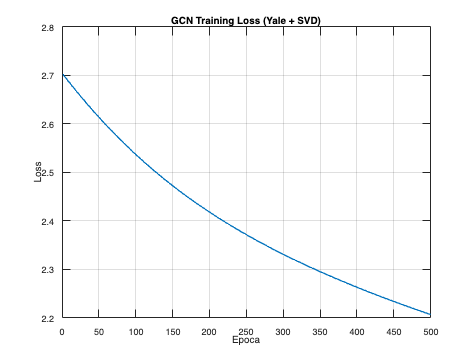


%% ----------------------------------------------------------------
%% 12) Visualizza training loss
%% ----------------------------------------------------------------
figure;
plot(1:epochs, loss_hist,'LineWidth',1.5);
xlabel('Epoca'); ylabel('Loss');
title('GCN Training Loss (Yale + SVD)');
grid on;
saveas(gcf, fullfile(results_path,'gcn_loss.png'));


fprintf('>>> Tempo totale: %.2f s\n', toc);

>>> Tempo totale: 67.16 s
